# 航空機ターボエンジンの残存耐用時間（RUL）予測（学習）

Copyright 2021 Michio Inoue

## 事前準備

ディレクトリ情報の確保

clear
settings = jsondecode(fileread('../settings.json'));
datadir = settings.PROCESSED_DATA_DIR

datadir = '../data/processed/'

modeldir = settings.MODEL_DIR

modeldir = '../models/'

変数名定義

% Model Health Parameters
eff_mod_list = ["fan_eff_mod";"fan_flow_mod";"LPC_eff_mod";"LPC_flow_mod";...
    "HPC_eff_mod";"HPC_flow_mod";"HPT_eff_mod";"HPT_flow_mod";
    "LPT_eff_mod";"LPT_flow_mod"];
meaneff_mod_list = "mean" + eff_mod_list;

% 追加で使用する変数も４つ追加（エンジンの状態評価に使用される変数）
var_list = [eff_mod_list; "T48";"SmFan";"SmLPC";"SmHPC"];
meanvar_list = "mean" + var_list;

## モデル学習

load(fullfile(datadir,'trainData.mat'),'trainData')

% 変数選択で試行錯誤しやすいようこの形にしておく
% （ここでは unit 番号を削るのみ）
trainDSUnitID = string(trainData.DS) + string(trainData.Unit);
% 学習用
subtrainData = trainData(:,["cycle","Y",meanvar_list',"Fc","hs","DS","p1","p2","score1"]);

### アンサンブル決定木の学習

以下のハイパーパラメータもベイズ最適化でチューニングします。

- [`Method`](https://www.mathworks.com/help/releases/R2021a/stats/fitrensemble.html?s_tid=doc_ta#bvcj_tw-1-Method) — 使用可能な方式は `'Bag'` または `'LSBoost'` です。

- [`NumLearningCycles`](https://www.mathworks.com/help/releases/R2021a/stats/fitrensemble.html?s_tid=doc_ta#bvcj_tw-1-NumLearningCycles) — `fitrensemble` は、既定では範囲 `[10,500]` の対数スケールで、正の整数を探索します。

- [`LearnRate`](https://www.mathworks.com/help/releases/R2021a/stats/fitrensemble.html?s_tid=doc_ta#mw_0b7f0d4a-2aae-4c52-a876-a6cb06c15ba4) — `fitrensemble` は、既定では範囲 `[1e-3,1]` の対数スケールで、正の実数を探索します。

- [`MinLeafSize`](https://www.mathworks.com/help/releases/R2021a/stats/fitrtree.html#bt6cr84-MinLeafSize) — `fitrensemble` は、範囲 `[1,max(2,floor(NumObservations/2))]` の対数スケールで整数を探索します。

単純に交差検定のためのデータ分割を行うだけなら 'OptimizeHyperparameters' オプションを 'auto' に設定するだけで良い（以下例）

ただ、今回は同じ unit からのデータが学習用・検証用データ両方に存在しないように分ける必要があるので、以下のコード。

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |      5.9987 |     0.70212 |      5.9987 |      5.9987 |      LSboost |           33 |     0.027547 |          516 |
|    2 | Accept |      7.4055 |      1.2482 |      5.9987 |      6.0745 |      LSboost |           53 |    0.0018978 |            2 |
|    3 | Best   |      4.1443 |       11.05 |      4.1443 |      4.1447 |      LSboost |          468 |     0.051433 |           32 |
|    4 | Best   |      4.0419 |       1.347 |      4.0419 |   

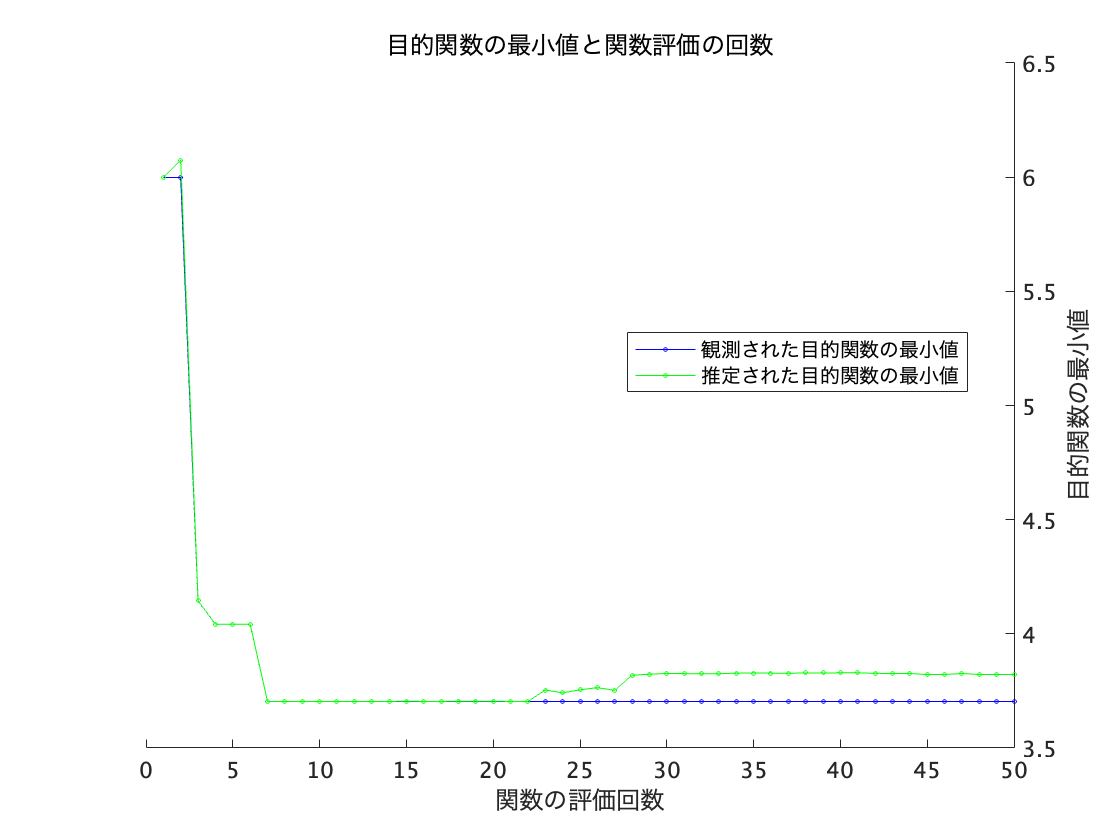


__________________________________________________________
最適化が完了しました。
MaxObjectiveEvaluations の 50 に達しました。
関数の評価回数の合計: 50
経過時間の合計: 251.5489 秒
目的関数の評価時間の合計: 222.8288

最適な観測実行可能点:
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    ___________

     Bag             21             0.2869          10     

観測された目的関数値 = 3.7037
推定される目的関数値 = 3.822
関数の評価時間 = 0.7178

最適な推定実行可能点 (モデルに基づく):
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    ___________

     Bag             21             0.2869          10     

推定される目的関数値 = 3.822
推定される関数評価時間 = 0.74982



rng(0)% 乱数シード固定（再現用）
NumObservations = height(subtrainData); % データ数
NumPredictors = width(subtrainData)-1; % 説明変数の数

% ベイズ最適化でチューニングする変数の定義
Method = optimizableVariable('Method',["Bag","LSboost"],'Type','categorical');
NumLearningCycles = optimizableVariable('NumLearningCycles',[10,500],'Transform','log','Type',"integer");
LearnRate = optimizableVariable('LearnRate',[1e-3,1],'Transform','log');
MinLeafSize = optimizableVariable('MinLeafSize',[1,max(2,floor(NumObservations/2))],'Transform','log','Type',"integer");

vars = [Method,NumLearningCycles,LearnRate,MinLeafSize];

% 目的関数定義（交差検定の誤差が目的変数）
fun = @(vars) myBayesGroup(vars,subtrainData,trainDSUnitID);

% UseParallel, true で並列処理（Parallel Computing Toolbox) できるが
% 結果の再現性が失われてしまうのでここでは並列処理なし
results = bayesopt(fun,vars,'UseParallel',false,...
    'AcquisitionFunctionName',"expected-improvement-plus",...
    'MaxObjectiveEvaluations',50);

最適値において再学習

optvars = results.XAtMinEstimatedObjective;
mdl = myBayesOptModel(optvars,subtrainData);

## 変数の重要度評価

tmp = predictorImportance(mdl);
[~,idx] = sort(tmp,'descend');
mdl.PredictorNames(idx)'

ans = 21×1 の cell 配列
    {'score1'          }
    {'cycle'           }
    {'meanHPT_eff_mod' }
    {'p1'              }
    {'meanLPT_eff_mod' }
    {'meanSmLPC'       }
    {'meanLPT_flow_mod'}
    {'hs'              }
    {'DS'              }
    {'meanHPC_flow_mod'}
    {'p2'              }
    {'meanHPC_eff_mod' }
    {'meanHPT_flow_mod'}
    {'meanfan_eff_mod' }
    {'meanLPC_flow_mod'}
    {'meanfan_flow_mod'}
    {'meanSmHPC'       }
    {'Fc'              }
    {'meanT48'         }
    {'meanLPC_eff_mod' }
    {'meanSmFan'       }


save(fullfile(modeldir,"model.mat"),'mdl');

## 学習データに対しての精度検証１

load(fullfile(modeldir,"model.mat"),'mdl');
predTrain = mdl.predict(subtrainData);
norm(predTrain-subtrainData.Y)

ans = 132.5295

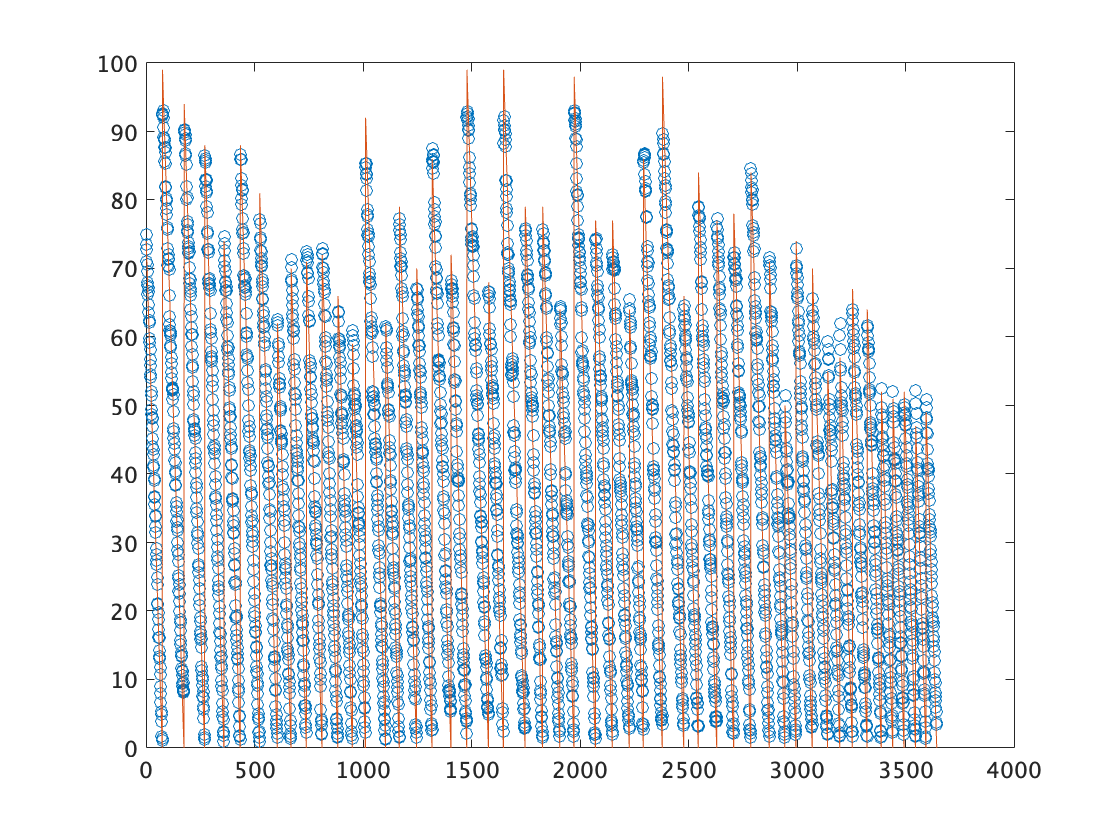


figure
plot(predTrain,'o');
hold on
plot(trainData.Y,'-')
hold off

## 学習データに対しての精度検証２

現時点では各フライトサイクルにおける RUL を予測しているが、ここで RUL は本来であれば傾き -1 で単調減少することを反映させて、傾き -1 の直線に近似する。その時の cycle = 1 (初回フライト時) の Y の値をその unit の RUL とする。

% unit 番号が変わるタイミングでデータを分割
diffUnit = diff(trainData.Unit);
idx = find(abs(diffUnit)>0)+1;
idx = [1;idx;height(trainData)];

% それぞれの unit で近似処理
%  y = - x + C;
Clist = 99:-1:40;
error = zeros(size(Clist));
Cfix = zeros(size(idx,1)-1,1);
Ctrue = zeros(size(idx,1)-1,1);
for jj=1:size(idx,1)-1
    tmp = predTrain(idx(jj):idx(jj+1)-1);
    for ii=1:length(Clist)
        C = Clist(ii);
        yy = C - (0:length(tmp));
        error(ii) = norm(yy-tmp);
    end
    [~,minidx] = min(error);
    Cfix(jj) = Clist(minidx);
    Ctrue(jj) = trainData.Y(idx(jj));
end

cycle = 1 (初回フライト時) の Y の値をその unit の RUL として誤差評価

[Cfix, Ctrue]

ans =     76    74
    99    99
    94    94
    88    88
    76    74
    88    88
    81    81
    63    62
    70    70
    75    71


sqrt(mean((Cfix-Ctrue).^2))

ans = 1.7786